eeg_data = load("data/100m.mat");

eeg = eeg_data.val(1, :);

freq = 250;
M = 5;
lphf_output = lhpf(eeg, M);

nlpf_output = nlpf(lphf_output, freq);

qrs_peaks = dec(nlpf_output, freq);

fileID = fopen('qrs_peaks.asc', 'w');

for i = 1:numel(qrs_peaks)
    fprintf(fileID, '0:00:00.00 %d N 0 0 0\n', qrs_peaks(i));
end

fclose(fileID);

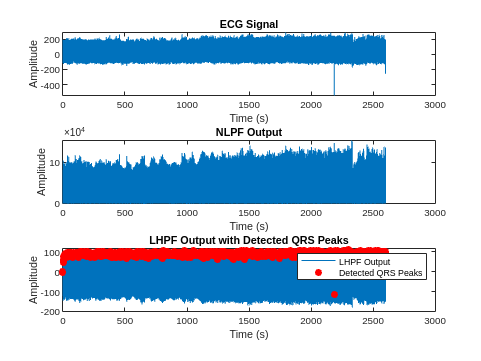


t = (0:length(eeg)-1) / freq;

figure;
subplot(3,1,1);
plot(t, eeg);
title('ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(t, nlpf_output);
title('NLPF Output');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t, lphf_output);
hold on;
scatter(qrs_peaks / freq, lphf_output(qrs_peaks), 'r', 'filled'); % Plot detected QRS peaks
title('LHPF Output with Detected QRS Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('LHPF Output', 'Detected QRS Peaks');